**奶制品的生产与销售:**

- 构建模型：


$$Max \ z=72x_1+64x_2 \\
满足以下条件: \\
\left \{ \begin{array}{l}
x_1+x_2 \leq50 \ 原材料在50桶以下\\
12x_1+8x_2 \leq 480  \ 工作时间在480小时以下\\
3x_1 \leq 100  \ x_1最多加工100 \\
x_1 \geq 0 \\
x_2 \geq 0
\end{array}\right. $$


- 代码求解:

clc;clear;
x = optimvar('x',2, 'LowerBound',0);                               % 设计变量
prob = optimproblem('ObjectiveSense','max','Objective',[72 64]*x); % 决策目标
prob.Constraints.con = [1 1;12 8;3 0]*x<=[50;480;100];             % 约束条件
[result,Max,~,~,lambda] = solve(prob);

Solving problem using linprog.

Optimal solution found.



result.x

ans =    20.0000
   30.0000


Max

Max = 3360

lambda.Constraints.con

ans =    48.0000
    2.0000
         0


**汽车厂生产计划 **

- 构建模型


$$Max \ z=2x_1+3x_2+4x_3 \\
\left \{ \begin{array}{l}
1.5x_1+3x_2+5x_3 \leq 600 \\
280x_1+250x_2+400x_3 \leq 60000 \\
x_1,x_2,x_3 \geq 0 \ 且都是整数
\end{array} \right.$$


- 代码求解：

clc;clear;
x=optimvar('x',3,Type='integer',LowerBound=0); % 规定x是整数
prob=optimproblem('ObjectiveSense','max','Objective',[2 3 4]*x);
prob.Constraints.con=[1.5 3 5;280 250 400]*x<=[600;60000];
[result,Max,~,~,lambda]=solve(prob);

Solving problem using intlinprog.
LP:                Optimal objective value is -632.258065.                                          

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -632.000000.                                                      
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



result.x

ans =    64.0000
  168.0000
         0


Max

Max = 632.0000

lambda.Constraints.con


ans =

     []



**汽车厂生产计划（进阶：非线性规划）**

- 建立模型


$$Max \ z=2x_1+3x_2+4x_3 \\
\left \{ \begin{array}{l}
1.5x_1+3x_2+5x_3 \leq 600 \\
280x_1+250x_2+400x_3 \leq 60000 \\
x_1(x_1-80) \geq 0 \\
x_2(x_2-80) \geq 0 \\
x_3(x_3-80) \geq 0
\end{array} \right.$$


- 代码求解

clc;clear;
objfun=@(x) [2 3 4]*x;
A=[1.5 3 5
  280 250 400];
b=[600;60000];
[result,fval,Max]=fminimax(objfun,rand(3,1),A,b,[],[],zeros(1,3),[],@bindfun_0);


Local minimum possible. Constraints satisfied.

fminimax stopped because the size of the current search direction is less than
twice the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


result

result = 1.0e-15 *

   -0.9766
   -0.2508
   -0.0000


fval

fval = -2.7057e-15

Max

Max = -2.7057e-15

***此题暂未求出解***

**选课问题：选科最少（0-1规划）**

- 建立模型


$$Min \ z=\sum_{i=1}^9x_i \\
题目要求 \ 
\left \{ \begin{array}{l}
x_1+x_2+x_3+x_4+x_5 \geq 2 \\
x_3+x_5+x_6+x_8+x_9 \geq 3 \\
x_4+x_6+x_7+x_9 \geq 2
\end{array} \right. \\
选科要求 \ 
\left \{ \begin{array}{l}
2x_3-x_1-x_2 \leq 0 \\
x_4-x_7 \leq 0 \\
2x_5-x_1-x_2 \leq 0 \\
x_6-x_7 \leq 0 \\
x_8-x_5 \leq 0 \\
2x_9-x_1-x_2 \leq 0
\end{array} \right. \\$$


- 代码求解：

clc;clear;
f=ones(1,9);
A=[-1 -1 -1 -1 -1 0 0 0 0
  0 0 -1 0 -1 -1 0 -1 -1
  0 0 0 -1 0 -1 -1 0 -1
  -1 -1 2 zeros(1,6)
  zeros(1,3) 1 zeros(1,2) -1 0 0
  -1 -1 0 0 2 zeros(1,4)
  zeros(1,5) 1 -1 0 0
  zeros(1,4) -1 0 0 1 0
  -1 -1 zeros(1,6) 2];
b=[-2;-3;-2;zeros(6,1)];
[x,Min]=intlinprog(f,1:9,A,b,[],[],zeros(1,9),ones(1,9));

LP:                Optimal objective value is 4.857143.                                             

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is 6.000000.                                                         
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



x

x =     1.0000
    1.0000
         0
         0
    1.0000
    0.0000
    1.0000
    1.0000
    1.0000


Min

Min = 6

**选课问题：多目标规划（0-1规划）**

f=[-5 -4 -4 -3 -4 -3 -2 -2 -3];
A=[-1 -1 -1 -1 -1 0 0 0 0
  0 0 -1 0 -1 -1 0 -1 -1
  0 0 0 -1 0 -1 -1 0 -1
  -1 -1 2 zeros(1,6)
  zeros(1,3) 1 zeros(1,2) -1 0 0
  -1 -1 0 0 2 zeros(1,4)
  zeros(1,5) 1 -1 0 0
  zeros(1,4) -1 0 0 1 0
  -1 -1 zeros(1,6) 2];
b=[-2;-3;-2;zeros(6,1)];
[x,Max]=intlinprog(f,1:9,A,b,[],[],zeros(1,9),ones(1,9));

LP:                Optimal objective value is -30.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



x

x =      1
     1
     1
     1
     1
     1
     1
     1
     1


-Max

ans = 30

可以发现，以最多学分作为目标函数与最少科目作为目标函数时是两个极端结果，这时可以使用**评价函数法.**

- **评价函数法**


$$目标函数 \ Min \ h(f(x))=\sqrt{(f_1(x)-min_1)^2-(f_2(x)-min_2)^2}$$


evaluatefun_0=@(x) sqrt(([1 1 1 1 1 1 1 1 1]*x-6)^2 + ([-5 -4 -4 -3 -4 -3 -2 -2 -3]*x+30)^2); % 目标函数
A=[-1 -1 -1 -1 -1 0 0 0 0
  0 0 -1 0 -1 -1 0 -1 -1
  0 0 0 -1 0 -1 -1 0 -1
  -1 -1 2 zeros(1,6)
  zeros(1,3) 1 zeros(1,2) -1 0 0
  -1 -1 0 0 2 zeros(1,4)
  zeros(1,5) 1 -1 0 0
  zeros(1,4) -1 0 0 1 0
  -1 -1 zeros(1,6) 2];
b=[-2;-3;-2;zeros(6,1)];
x0=zeros(9,1); % 令初始值为[0 0 0 0 0 0 0 0 0]'
[x, fval, exitflag]=fmincon(evaluatefun_0,x0,A,b,[],[],zeros(1,9),ones(1,9)); % 非线性规划求解器


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.4000
    1.0000


fval

fval = 2.6833

Max=[5 4 4 3 4 3 2 2 3]*x

Max = 28.8000

**动态规划**

- 最短路径

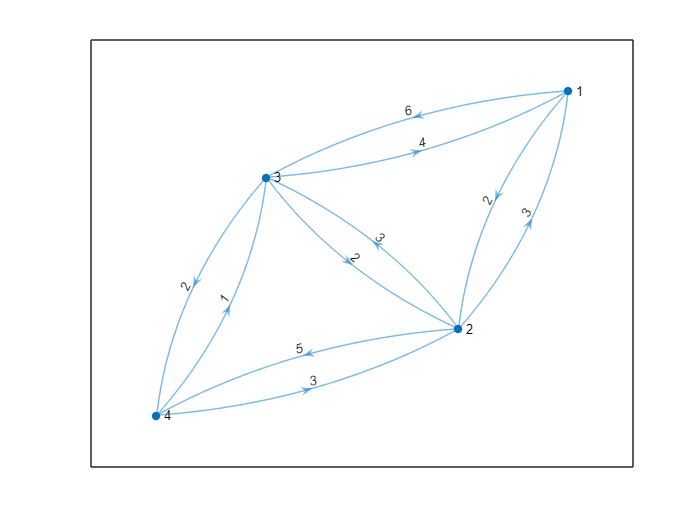

clc;clear;
% w=zeros(4);
% w(1,2)=2;w(2,3)=3;w(1,3)=6;w(2,4)=5;w(3,4)=2;
% w(2,1)=3;w(3,2)=2;w(3,1)=4;w(4,2)=3;w(4,3)=1;
% g=digraph(w);
s=[1 1 2 2 2 3 3 3 4 4];
t=[2 3 4 1 3 1 4 2 2 3];
w=[2 6 5 3 3 4 2 2 3 1];
g=digraph(s,t,w);
plot(g,'EdgeLabel', g.Edges.Weight)

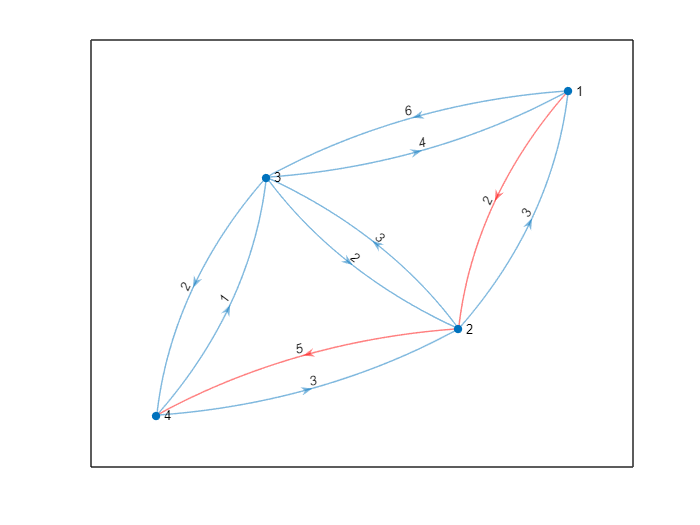

[P,d]=shortestpath(g,1,4);
shortplot = plot(g, 'EdgeLabel', g.Edges.Weight);
highlight(shortplot,P,'EdgeColor','r')

Result=distances(g); % 把任意两点的最短路径求解出来并放在Result这个矩阵中
Result(1,4)

ans = 7

[nodeIDs,dist]=nearest(g,1,6) % 返回所有与节点1距离6内的节点

nodeIDs =      2
     3


dist =      2
     5


**设备更新，使总的支付费用最少（经典动态规划问题）**

工厂的某台机器可连续工作四年，决策者每年年初都要决定机器是否需要更新。若更新，就要支付购置费用；若不更新，则要支付维修与运行费用，且随着机器使用年限的增加维修与运行费用逐年增多。计划期（4年）中每年年初的购置价格及各个年限内维修与运行费用由表1给出，（1）试制订今后4年的机器更新计划，使总的支付费用最少。

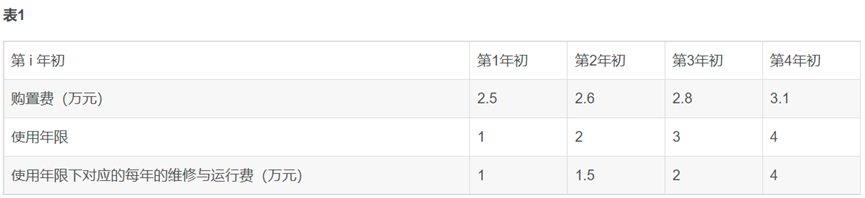

- 建立模型

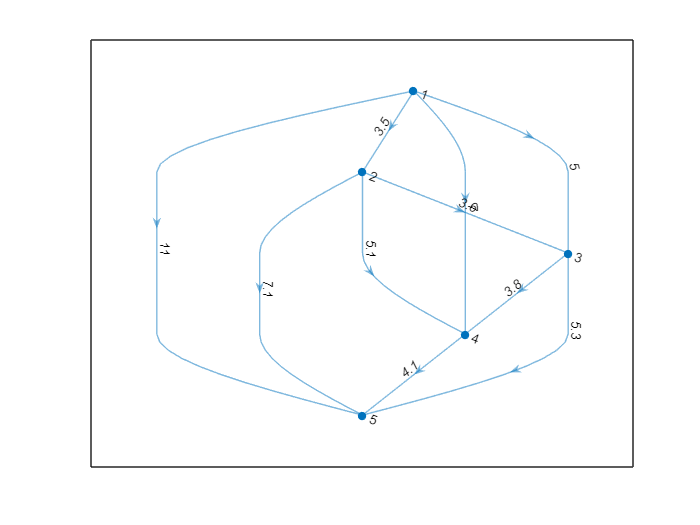

clc;clear;
s=[1 1 1 1 2 2 2 3 3 4];
t=[2 3 4 5 3 4 5 4 5 5];
w=[3.5 5 7 11 3.6 5.1 7.1 3.8 5.3 4.1];
G=digraph(s,t,w);
plot(G,'EdgeLabel', G.Edges.Weight);

- 求解最短路径

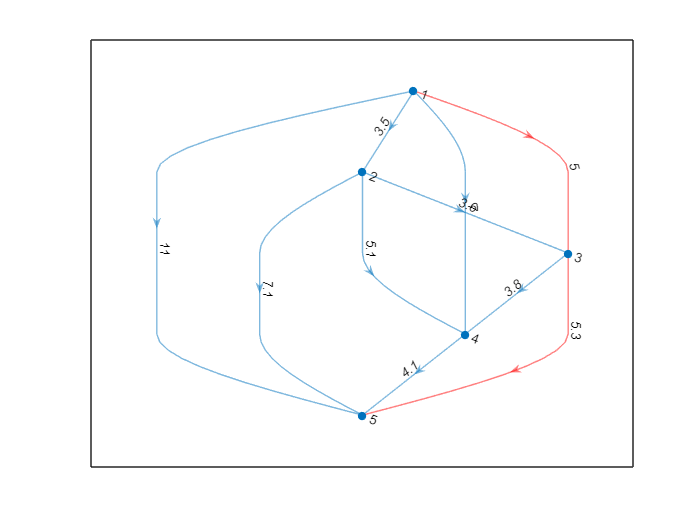

[P,d]=shortestpath(G,1,5);
shortplot = plot(G, 'EdgeLabel', G.Edges.Weight);
highlight(shortplot,P,'EdgeColor','r');

Result=distances(G,1,5)

Result = 10.3000